clear; clc;

%% Initial conditions at t=0
CA_init = 10;    % mol/m^3
CB_init = 18;    % mol/m^3
CC_init = 0;     % mol/m^3
T_init = 343;     % K
y0 = [CA_init; CB_init; CC_init;T_init];

## Set constant Tj and T0

T0 = 343;        % K
Tj = 343;        % K

PARAMS = [T0 Tj]

PARAMS =    343   343



%% Time span
tspan = [0 3600];  % seconds (60 minutes)


MASS = eye(4,4);
OPTIONS = odeset('Mass',MASS);

%% ODE system
odefun = @(t, y) daeSystemLHS(t, y, PARAMS);


tic;
[t1, y1] = ode45(odefun, tspan, y0, OPTIONS);
time_ode45 = toc

time_ode45 = 0.0049


tic;
[t2, y2] = ode15s(odefun, tspan, y0,OPTIONS);
time_ode15s = toc

time_ode15s = 0.0114


tic;
[t3, y3] = ode23s(odefun, tspan, y0, OPTIONS);
time_ode23s = toc

time_ode23s = 0.0042

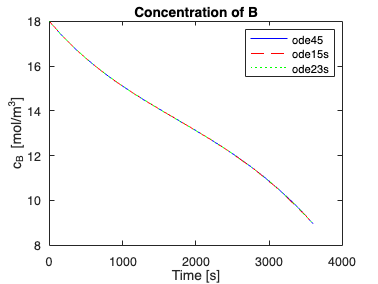

plot(t1, y1(:,2), 'b', t2, y2(:,2), 'r--', t3, y3(:,2), 'g:');
title('Concentration of B');
xlabel('Time [s]'); ylabel('c_B [mol/m^3]');
legend('ode45', 'ode15s', 'ode23s');

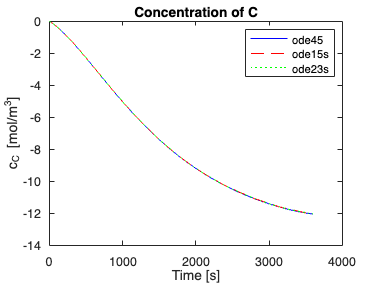

plot(t1, y1(:,3), 'b', t2, y2(:,3), 'r--', t3, y3(:,3), 'g:');
title('Concentration of C');
xlabel('Time [s]'); ylabel('c_C [mol/m^3]');
legend('ode45', 'ode15s', 'ode23s');

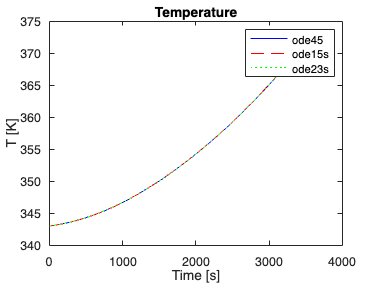

plot(t1, y1(:,4), 'b', t2, y2(:,4), 'r--', t3, y3(:,4), 'g:');
title('Temperature');
xlabel('Time [s]'); ylabel('T [K]');
legend('ode45', 'ode15s', 'ode23s');
legend('ode45', 'ode15s', 'ode23s');

## **sensitivity analysis**

T0_values = [343, 348, 338, 343, 343];
Tj_values = [343, 343, 343, 348, 338];

labels = [
    "Baseline";
    "T₀ +5K";
    "T₀ -5K";
    "Tⱼ +5K";
    "Tⱼ -5K"
];

all_t = cell(5,1);   
all_y = cell(5,1);   

for i = 1:5
    PARAMS = [T0_values(i) Tj_values(i)]
    odefun = @(t, y) daeSystemLHS(t, y, PARAMS);

    [t, y] = ode45(odefun, tspan, y0,OPTIONS);
    all_t{i} = t;
    all_y{i} = y;  % y(:,1)=cA, y(:,2)=cB, y(:,3)=cC, y(:,4)=T
end

PARAMS =    343   343


PARAMS =    348   343


PARAMS =    338   343


PARAMS =    343   348


PARAMS =    343   338


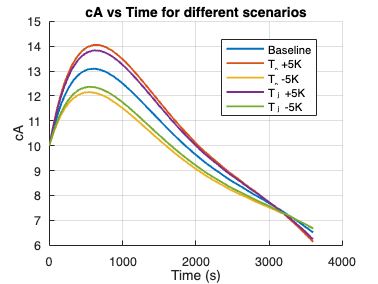

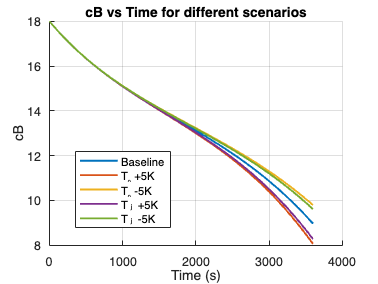

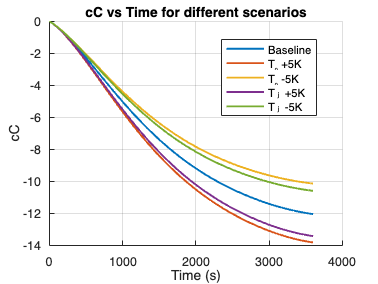

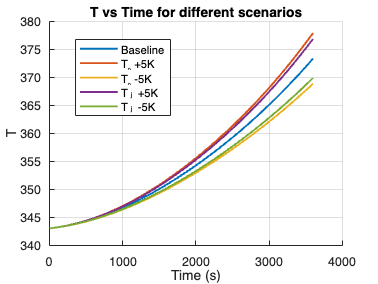


vars = {'cA', 'cB', 'cC', 'T'};
for k = 1:4
    figure;
    hold on; grid on;
    for i = 1:5
        plot(all_t{i}, all_y{i}(:,k), 'LineWidth', 1.5);
    end
    xlabel('Time (s)');
    ylabel(vars{k});
    title([vars{k} ' vs Time for different scenarios']);
    legend(labels, 'Location', 'best');
end